# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_cake.mlx
    ----------------
    This code solves the deterministic cake-eating problem using value function iteration.

%}

## The Model.

The optimization problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{W_t\}_{t=2}^{\infty}}{\text{max }} \sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } W_{t+1} = W_t - c_t \text{ ,}\end{array} \ \text{for} \ t = 1, 2, ...$$



$$c_t > 0, W_t > 0 \text{ .}$$


## Recursive Formulation.

The recursive formulation is


$$V_t(W_t) = \underset{c_t, W_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(W_{t+1})$$


 
$$\begin{array}{r l} \text{s.t. } W_{t+1} = W_t - c_t \text{ ,}\end{array} \ \text{for} \ t = 1, 2, ...$$



$$c_t > 0, W_t > 0 \text{ .}$$


Substituting the constraint gives


$$V_t(W_t) = \underset{W_{t+1}}{\text{max}}\frac{\left(W_t-W_{t+1}\right)^{1-\sigma}}{1-\sigma} + \beta V_{t+1}(W_{t+1})$$



$$W_t \geq 0 \text{ .}$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:/Users/',id,'/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_cake_matlab/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:/Users/xmgb/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/code/vfi_cake_matlab/ 



## Set the parameters and generate the state space.

Calls: model.m.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration (VFI) on the grid.

Calls: solve.m, and model.m.

t = cputime;
sol = solve.cs_model_inf(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------


Converged in 1 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.0000 seconds.


## Simulate Model.

Calls: simulate.m

sim = simulate.cake(par,sol); % Simulate the model.

## Plot the policy functions.

Calls: my_graph.m.

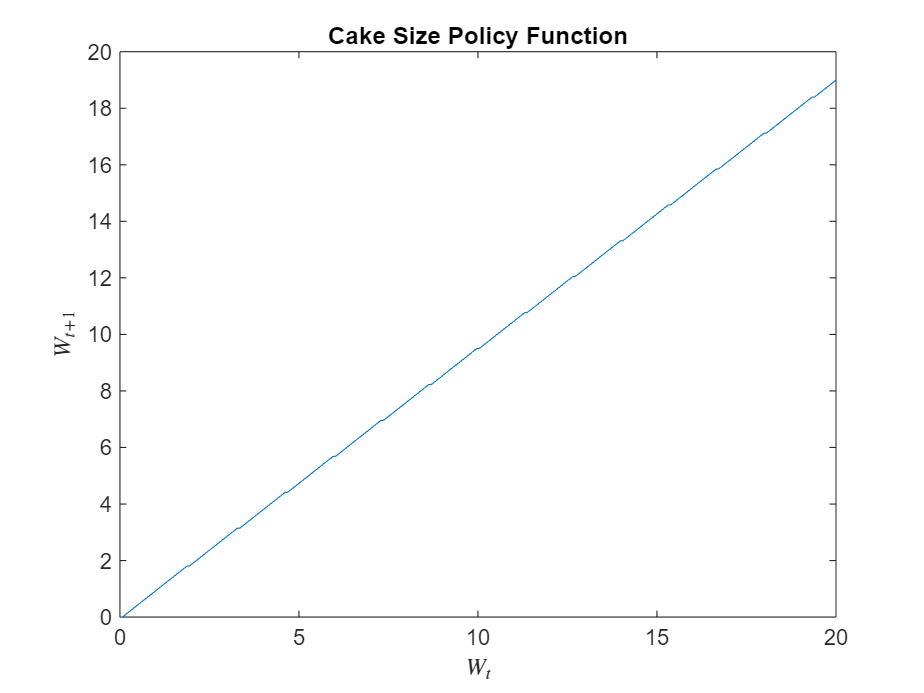

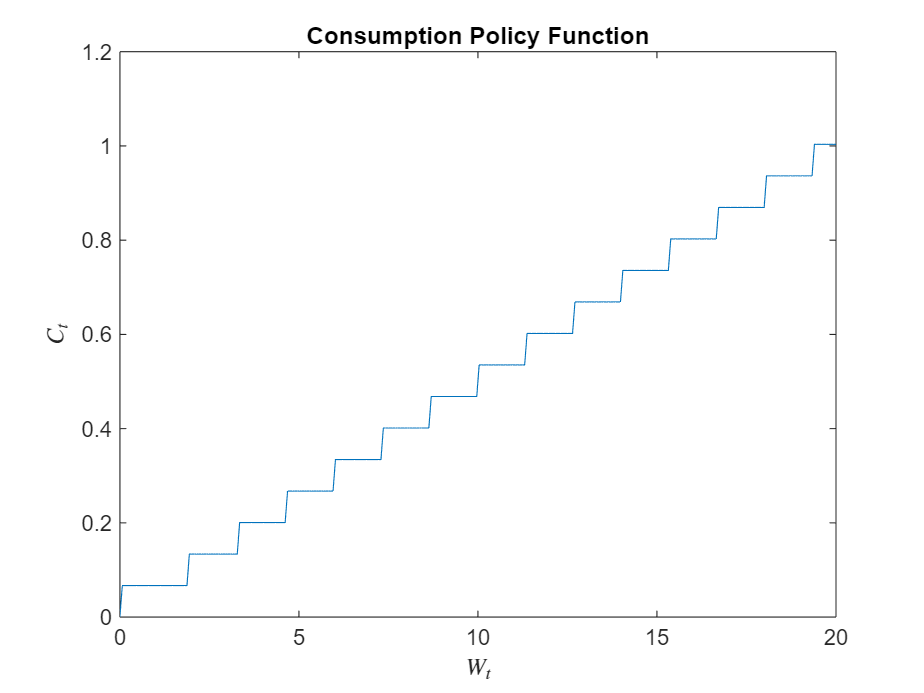

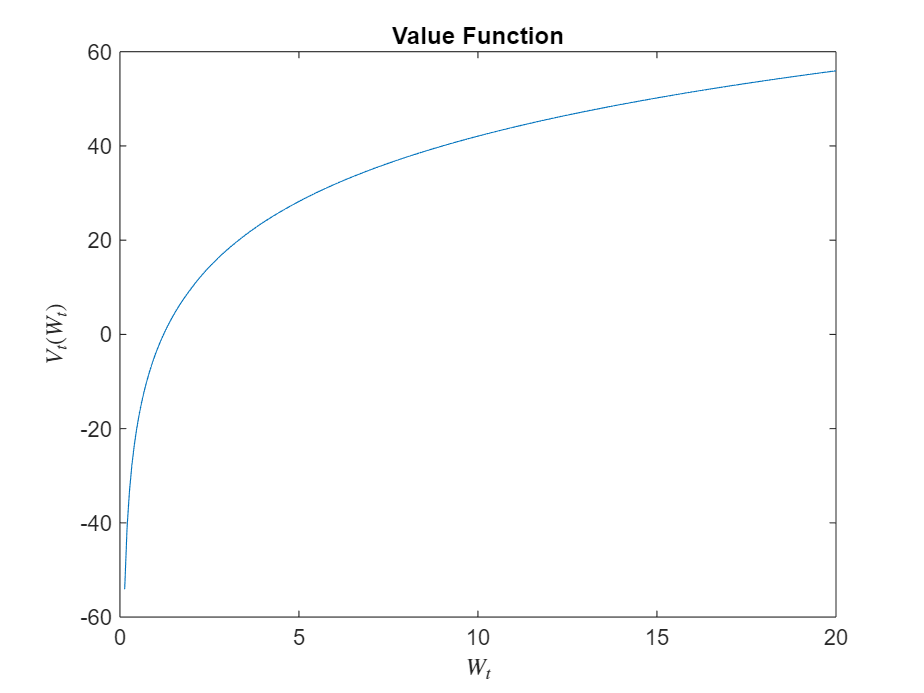

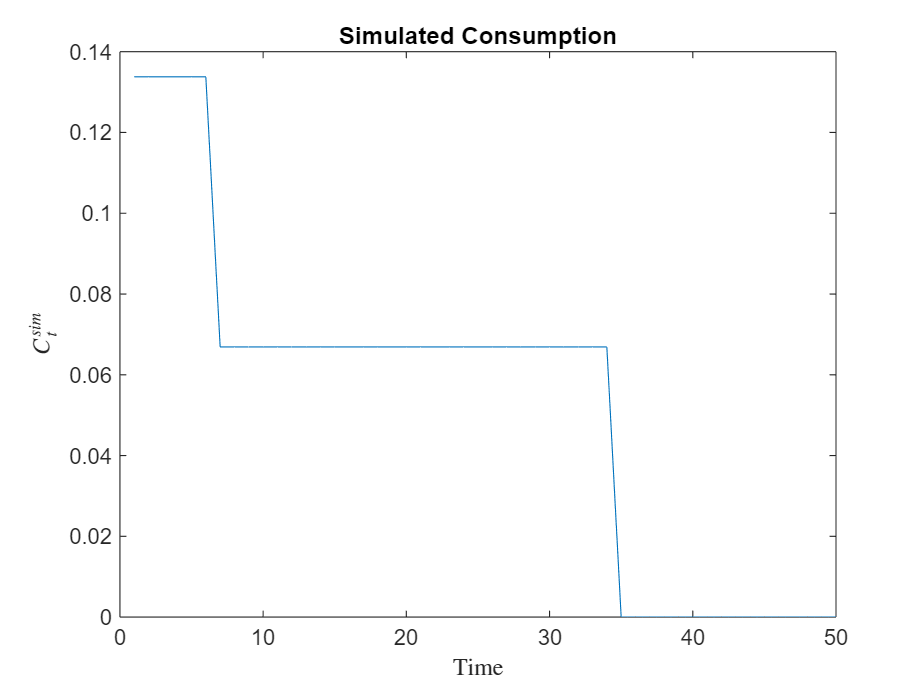

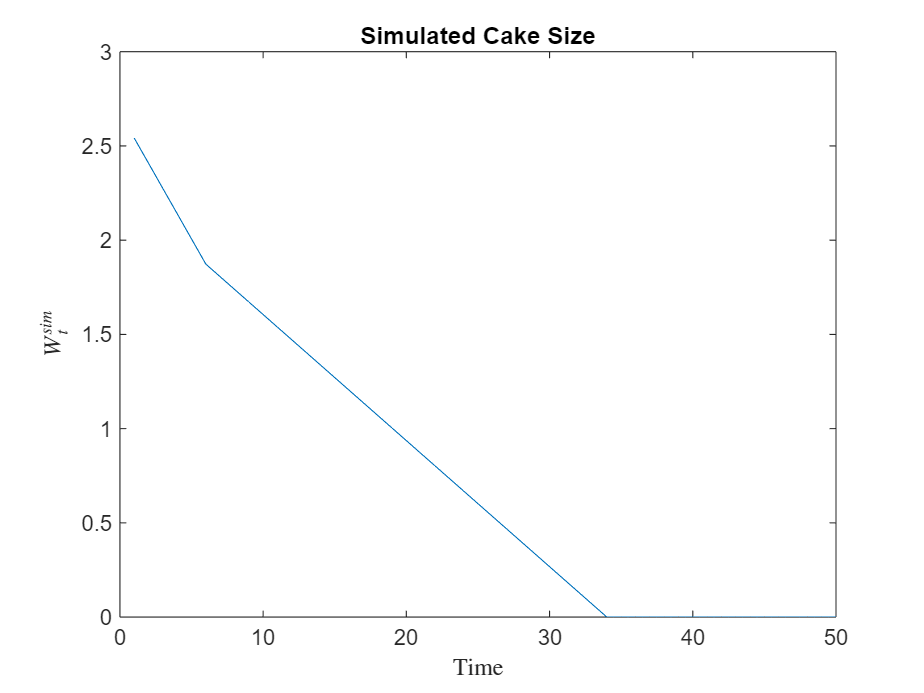

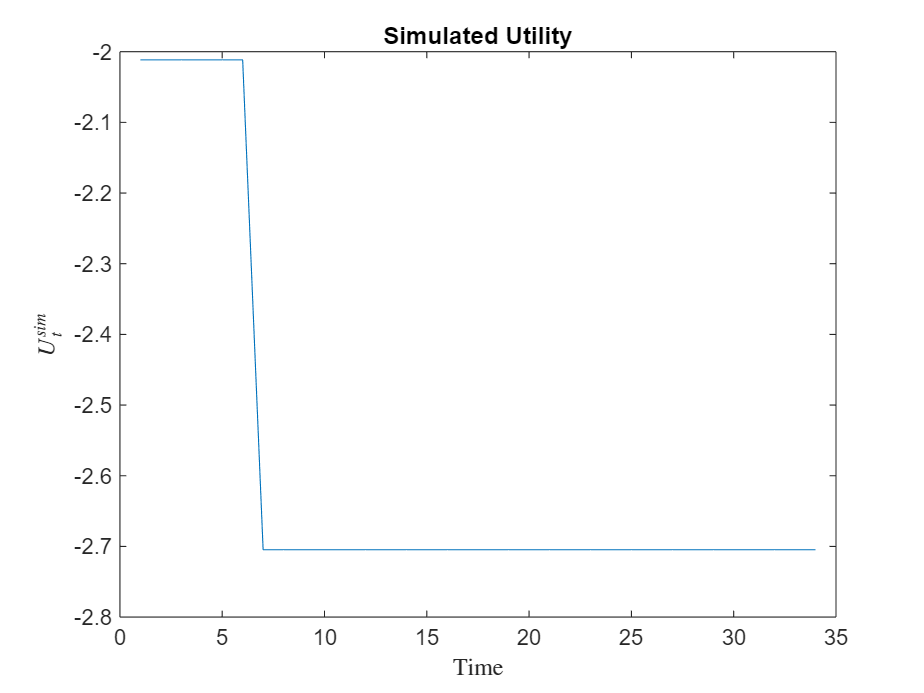

my_graph.plot_policy(par,sol,sim,figout)